# Esempio di interpolazione dei dati

In questo elaborato varranno analizzati degli esempi significativi di interpolazione dei dati, utilizzando gli strumenti messi a disposizione dal **M**`atlab`. Prima di dare uno sguardo a questi esempi, vedremo un semplice tool sviluppato per provare le diverse tecniche di interpolazione che mette abbiamo a disposizione il **M**`atlab`, poi continueremo con degli esempi di interpalazione e con degli esempi di previsione effettuata a partire da un dataset di cui si conoscono anche i valori per cui stiamo effettuando la previsione e infine vedremo degli esempi di smoothing.

# Interpolazione

## plotInterpolation: Tool per il confronto di tecniche di interpolazioni diverse

Per confrontare le diverse tecniche di interpolazione che il matlab mette a disposizione, è stato realizzato un tool che permette di selezionare dei punti con il mouse su una finistra e di interpolarli utilizzando una delle diverse tecniche messa a disposizione dal M`atlab`. Nella versione corrente sono disponibili le seguenti tecniche di interpolazione : *lineare*, *polinomiale e* *spline naturale. *Il codice, per il tool realizzato , è disponibile nel file` plotInterpolation.m. `

### Utilizzo tool interpolazione

Per utilizzare il tool bisogna seguire i seguenti passi :

- Cliccare sul tasto `'Seleziona punti';`

- Utilizzare il tasto sinistro del mouse per selezionare i punti con ordine di ascissa crescente ;

- Utilizzare il tasto destro del mouse per selezionare l'ultimo punto, che avrà il più elevato valore di ascissa ;

- Selezionare il tipo di interpolazione desiderata dal menù a tendina ;

- Premere il testo` ' Reset Data '` per ripetere il processo oppure premere il tasto `' Close '` per uscire dal tool.

### Esempi di funzionamento del tool

Di seguito sono riportati alcuni esempi, attraverso i quali si può facilmente verificare che attraverso l'interpolazione lineare si ottiene una "curva" spigolosa, poco regole e che ha una derivata che presenta delle discontinuità nei punti di partenza per l'interpolazione. Utilizzando l'interpolazione polinomiale, si ha una curva più regolare ma all'aumentare del numero di punti e quindi del grado del polinomio si presentano fenomeni oscillatori la cui ampieza può essere anche molto grande rispetto ai volori considerati e quindi si andrebbe a descrivere un fenomeno completamente diverso. Infine si osserva che la spline naturale è il miglior metodo per l'interpolazione di punti indipendentemente dal numero di punti che si voglia interpolare.

**Esempio con pochi punti (5)**

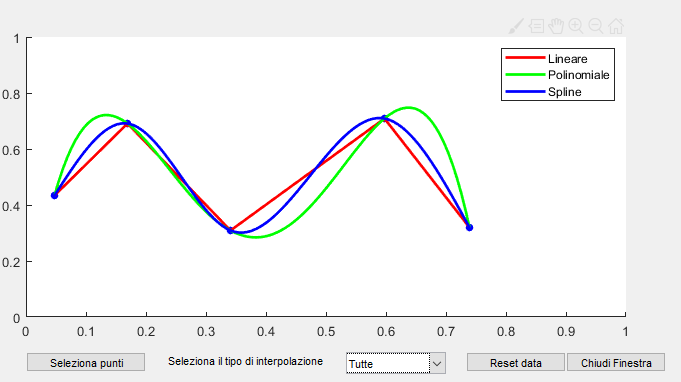

In questo caso la curva ottenuta con il polinomio interpolante non presenta oscillazioni.

**Esempio con un numero maggiore di punti**

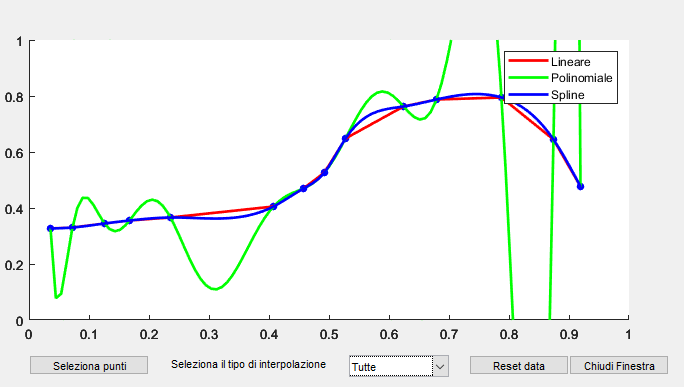

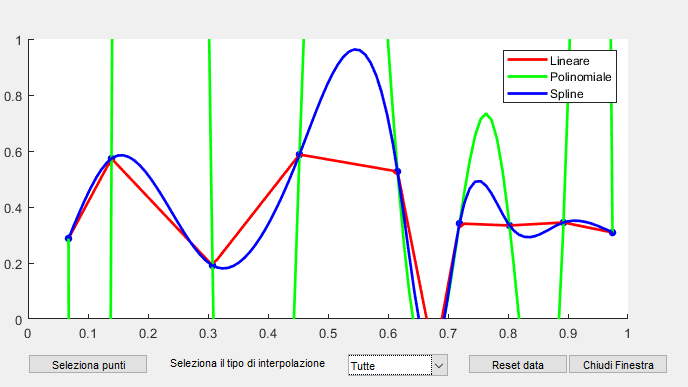

In questi caso la curva ottenuta mediante interpolazione con il polinomio, presenta delle oscillazioni. Inoltre si può anche osservare come nella prima figura di questo esempio, la curva ottenuta mediante interpolazione lineare, sia molto simile a quella ottenuta mediante l'uso della spline. Infatti non bisogna dimenticare che al crescere del numero di punti e al diminuire della distanza tra essi l'interpolazione lineare converge alla curva reale e in questo caso anche a quella generata dalla spline naturale.

## Consumo medio di plastica nel mondo dal 1950 al 2015 

In questo paragrafo si utilizzeranno le tecniche di interpolazione viste precedentemente su un dataset reale. In particolare si è scelto come dataset quello che descrive il consumo medio di plastica nel mondo ( espresso in tonnellate ) a partire dagli anni '50 fino al 2015. Tale dataset è stato scaricato dal seguente sito: [https://ourworldindata.org/plastic-pollution](https://ourworldindata.org/plastic-pollution) .

Il dataset scelto contiene tutti i dati di consumo nel periodo di riferimento, però per comprendere al meglio la potenzialità delle funzioni interpolanti offerte dal matlab si rimuoveranno alcuni dati dal dataset per poter poi utilizzare la spline per recuperare informazioni nel periodo non noto e ricostruire l'adamento. Costruendo così l'esempio possiamo confrontare i risultati ottenuti, con l'utilizzo della spline, con l'andamento reale. 

**Nota:** i risultati ottenuti di seguito sono stati ottenuti eliminando dal dataset originale degli elementi scelti a caso, pertanto esecuzioni differenti porteranno a risultati e in alcuni casi osservazoni leggermente diverse, ma sicuramente non discordi con quelle fatte di seguito.

### **Andamento reale a partire dal dataset completo**

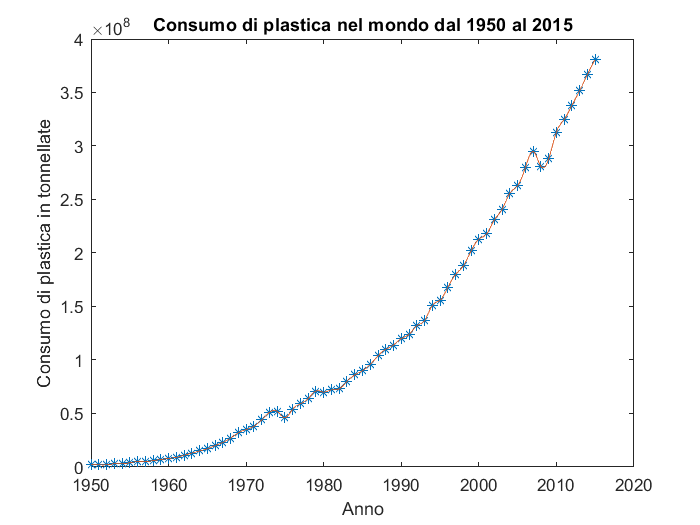

% Carico il dataset
clear;
M        = csvread('global-plastics-production.csv',1,2);
years    = M(:,1);
plastics = M(:,2);

% Interpolo i dati con la spline
ppSpline    = spline(years,plastics);
t           = 1950:0.1:2015;
yReal       = ppval(ppSpline,t);

plot(years,plastics,'*',t,yReal)
title('Consumo di plastica nel mondo dal 1950 al 2015')
xlabel('Anno')
ylabel('Consumo di plastica in tonnellate')

### Estrazione di un sottoinsime di punti dal dataset originario e ricostruzione con la spline

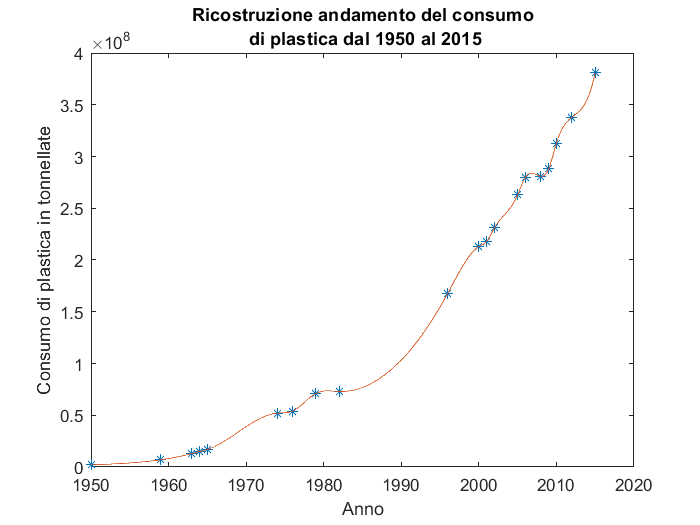

y=years; p=plastics;
% Rimuovo dei dati dal dataset per controllare come la spline ricostruisce
% l'andamento 
% Nota i dati sono rimossi in modo random 
for i=1:46
    ri=ceil(rand*26+1);
    y(ri)=[];
    p(ri)=[];
end

pp  = spline(y,p);
t       = 1950:0.1:2015;
ySpline = ppval(pp,t);

plot(y,p,'*',t,ySpline)
title({'Ricostruzione andamento del consumo',' di plastica dal 1950 al 2015'})
xlabel('Anno')
ylabel('Consumo di plastica in tonnellate')

A questo punto, in seguito all'interpolazione dei punti estratti, andiamo a confrontare i risultati ottenuti, in termine di andamento della funzione, con il caso reale.

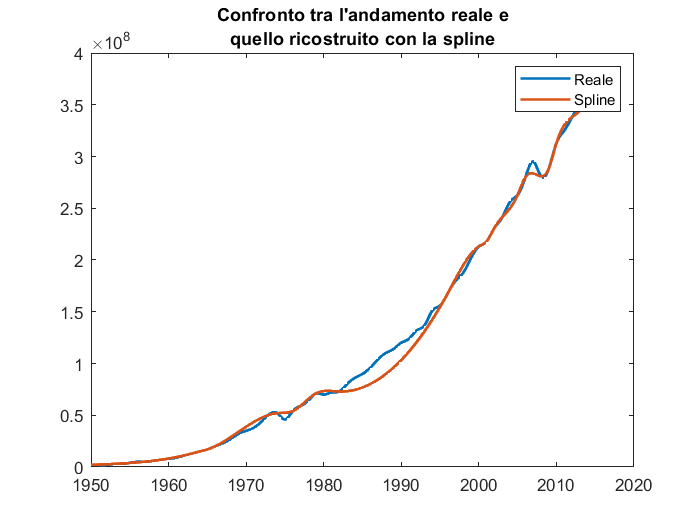

plot(t,yReal,t,ySpline,'LineWidth',1.5)
title({'Confronto tra l''andamento reale e', 'quello ricostruito con la spline'})
legend('Reale','Spline')

Anche se l'andamento è stato ricostruito utilizzando solo i dati di 20 anni scelti casualmente tra i 66 disponibili nel dataset, la curva ottenuta è molto simile a quella originaria e la funzione interpolante evidenzia, ancora, che l'utilizzo della plastica nel mondo è in aumento.

Per avere un idea della bontà della soluzione trovata con la spline, andiamo a plottare su uno stesso grafo i punti del dataset originale e la curva ottenuta con la spline in modo tale da verificare se la curva generata con la spline copre molti dei punti del dataset di partenza.

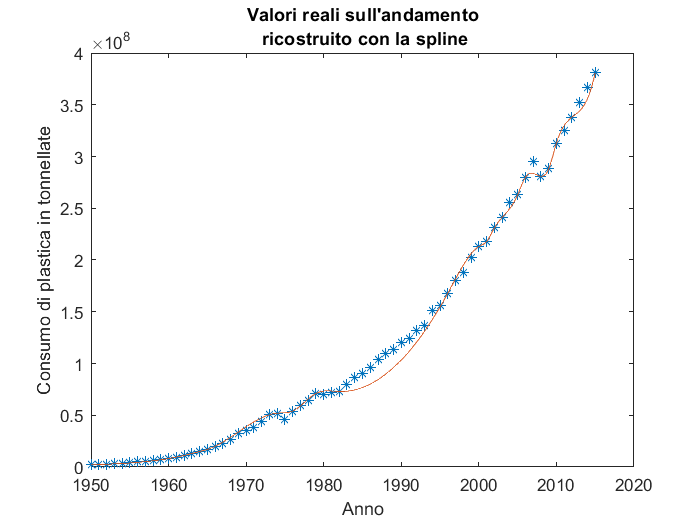

plot(years,plastics,'*',t,ySpline)
title({'Valori reali sull''andamento',' ricostruito con la spline'})
xlabel('Anno')
ylabel('Consumo di plastica in tonnellate')

Analizzato il caso migliore di interpolazione con la spline, andiamo ad analizzare ora le differenza che si avrebbero nell'andamento nel caso in cui utilizziamo l'interpolazione lineare o polinomiale per ricostruire l'andamento.

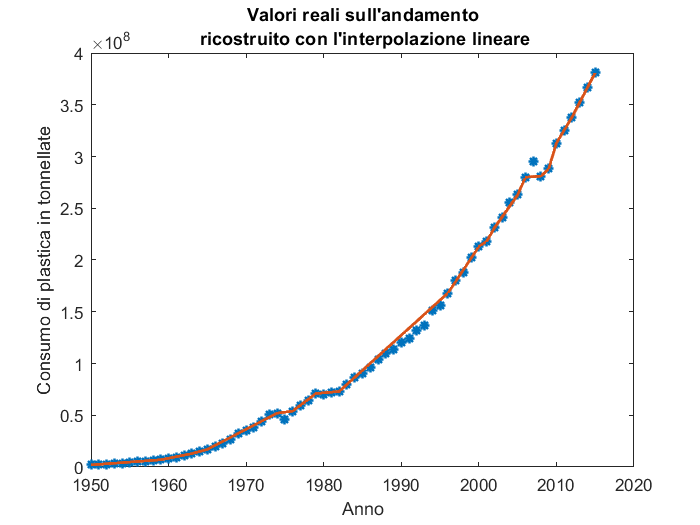

ptLin = interp1(y,p,t);
plot(years,plastics,'*',t,ptLin,'LineWidth',1.5)
title({'Valori reali sull''andamento',' ricostruito con l''interpolazione lineare'})
xlabel('Anno')
ylabel('Consumo di plastica in tonnellate')

**Nota:** In questo caso l'interpolazione lineare si comporta molto bene, infatti non dimentichiamo che la curva ottenuta mediante interpolazione lineare converge a quella reale al crescere dei punti. 

Viste le due tecniche di intepolazioni precedenti, vediamo anche il risultato dell'interpolazione mediante polinomio di grado n.

ptPol = polyval(polyfit(y,p,length(y)-1),t);

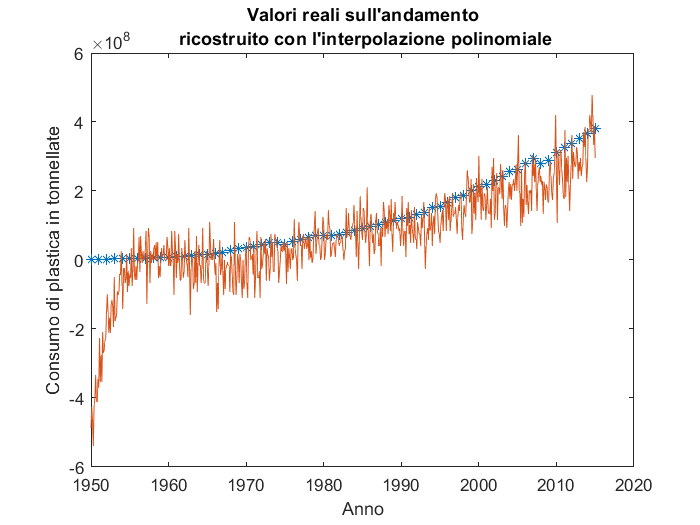

plot(years,plastics,'*',t,ptPol)
title({'Valori reali sull''andamento',' ricostruito con l''interpolazione polinomiale'})
xlabel('Anno')
ylabel('Consumo di plastica in tonnellate')

**Nota: **Come ci aspettavamo l'interpolazione polinomiale, al crescere del numero di punti, genera oscillazioni pertanto anche se l'andamento può sembrare simile a quello reale, si che la curva ottenuta presenta molte oscillazioni. 

### Estrapolazione dati e previsione futuro

Per osservare le funzionalità offerte dal matlab in merito all'estrapolazione e previsione futura dell'andamento si è deciso di rimuovere dal dataset ridotto dell'esempio precendete i dati dal 2005 in poi così da poter ricostruire l'andamento e confrontarlo con quello reale.

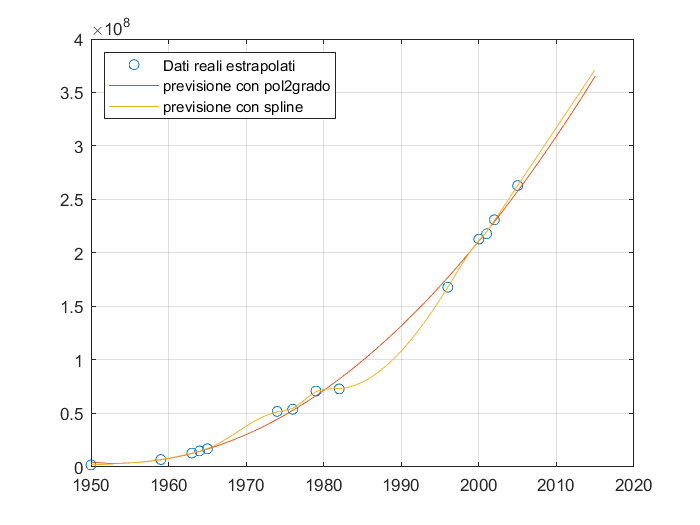

%Rimuovo i dati dal 2005 in poi per poter fare un esempio di previsione
p([y>2005])=[];
y([y>2005])=[];

% Previsione futura e realizzazione approssimazione andamento con la 
% spline cubica con polinomio di secondo grado 
pp = fnxtr(csaps(y,p,.85));
[pol,~,mu] = polyfit(y,p,2);

% Calcolo dei punti che servono per effettuare il plot
x_a=1950:1:2015; 
% polinomio
yPolinomio = polyval(pol,x_a,[],mu); 
% spline
ySpline=ppval(pp,x_a);   

p1 = plot(y,p,'o',x_a,yPolinomio,x_a,ySpline);
grid,legend('Dati reali estrapolati','previsione con pol2grado','previsione con spline','Location','northwest')

Entrambe le previsioni generate sono molto fedeli al caso reale, infatti riusciamo chiaramente ad evincere che il consumo di plastica è in aumento, di seguito analizzeremo meglio le due previsoni ottenute.

Partiamo dalla previsione ottenuta mediante il polinomio di secondo grado. Dalla figura si evince che la plastica è chiaramente in aumento ma non tutti i punti del dataset di partenza vengono coperti per bene, ciò la curva ci passa vicino al punto ma non per quel punto.

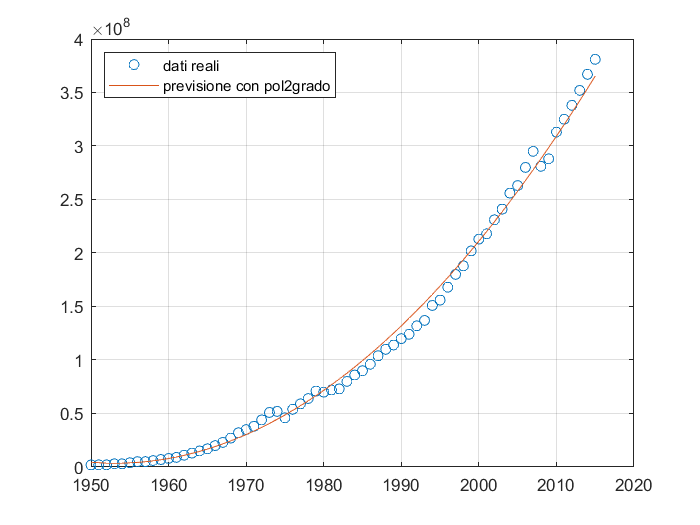

plot(years,plastics,'o',x_a,yPolinomio)
grid,legend('dati reali','previsione con pol2grado','Location','northwest')

Verifichiamo di seguito la qualità della previsione ottenuta mediante interpolazione con la spline.

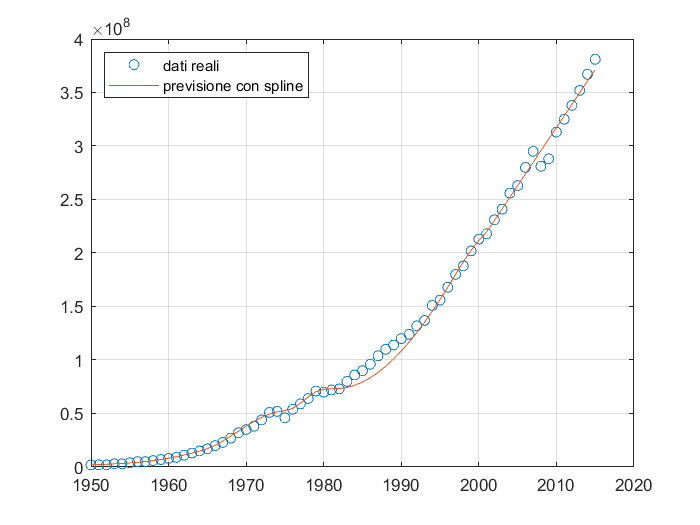

plot(years,plastics,'o',x_a,ySpline)
grid, legend('dati reali','previsione con spline','Location','northwest')

Notiamo che, in questo caso, che anche se l'approsimazione con il polinomio di secondo grado è buona,  quella con la spline è migliore. Infatti osservando bene le due figure si nota che la spline approssima meglio l'andamento reale, infatti i punti del dataset reale si dispongono meglio sulla curva generata con la spline.

Andiamo ad analizzare analiticamente il risultato appena osservato. Calcoliamo il residuo tra i punti che compongono la curva, ottenuta utilizzando la spline, e quelli del dataset originale e il residuo tra i punti del polinomio di secondo grado e quelli del dataset originale.

yRe = ppval(ppSpline,x_a);

res_pol = yRe - yPolinomio;
res_spl = yRe - ySpline;
mean(abs(res_pol))

ans = 5.5607e+06

mean(abs(res_spl))

ans = 3.6158e+06

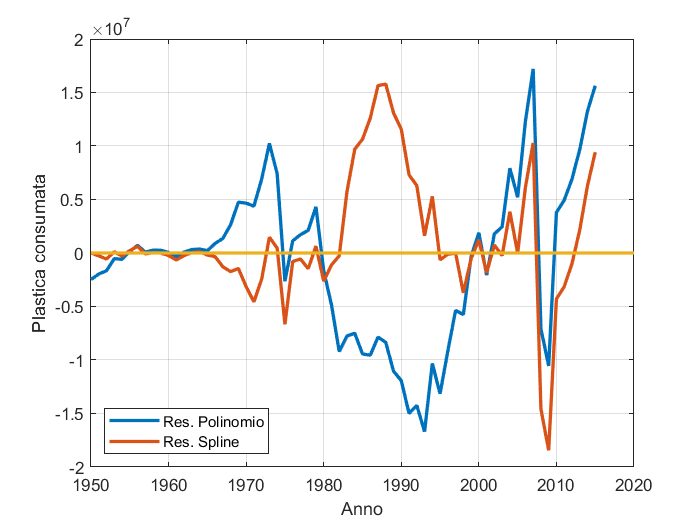

data = [res_pol' res_spl'];
p = plot(x_a,data,[1950 2020],[0 0],'Linewidth',2); xlabel('Anno'), ylabel('Plastica consumata'),...
    legend('Res. Polinomio', 'Res. Spline','Location','southwest'), grid;

## Interpolazione di curve nel piano 

In questo esempio analizzeremo come procedere all'interpolazione di una curva parametrica. Come curva del piano si è scelta la `Lemniscata di Bernoulli` che raffigura il simbolo dell'infinito. Nell'esempio osserveremo come da pochi punti dell'equazione parametrica possiamo ricostruire, utilizzando la spline, una figura molto simile a quella della Lemniscata scelta. 

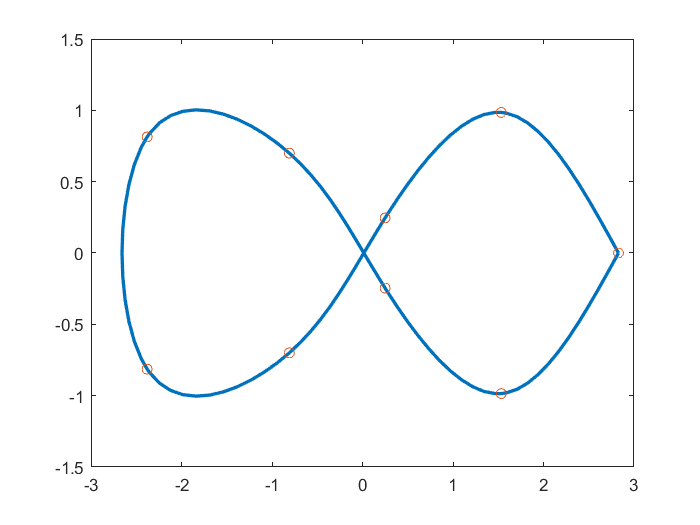

t=linspace(0,2*pi,10);

% Equazioni della Leminiscata
x=(2*sqrt(2)*cos(t))./(1+sin(t).^(2));
y=(2*sqrt(2)*cos(t).*sin(t))./(1+sin(t).^(2));

% Interpolazione con la spline cubica
points=[x;y];
pp=cscvn(points);
fnplt(pp); hold on

plot(points(1,:),points(2,:),'o')
hold off

La curva chiusa ottenuta mediante interpolazione di 9 punti è molto simile al simbolo dell'infinito, e di conseguenza possiamo ritenerci soddisfatti del risultato ottenuto.

## Interpolazione bidimensionale

Di seguito si riporta un esempio di interpolazione dei una curva parametrica bidimensionale.

Innanzitutto è stato costruita una curva parametrica come segue:

u = linspace(0,2*pi,20);
v = linspace(-1,1,10);
[u,v] = meshgrid(u,v);

%Nastro di Moebius
%x = (1+v.*cos(u/2)).*cos(u);
%y = (1+v.*cos(u/2)).*sin(u);
%z = v.*sin(u/2);

%Curva deriviata dalle equazioni che descrivono la
% cucitura della pallina da tennis
x = v.*cos(u) + 3.*cos(3*u);
y = v.*sin(u) - 3.*sin(3*u);
z = 10.*sin(2*u);

Di default matlab usa l'interpolazione lineare e essendo il numero di punti, su cui andremo a costruire la supefice, molto piccolo avremo una superficie spigolasa e poco regolare.

figure(4)
surf(x,y,z), colormap hsv
view([20,25,30])

Pertanto, per migliorare la superficie si è proceduto ad eseguire l'interpolazione con la funzione `interp2 `utilizzando come method la spline :

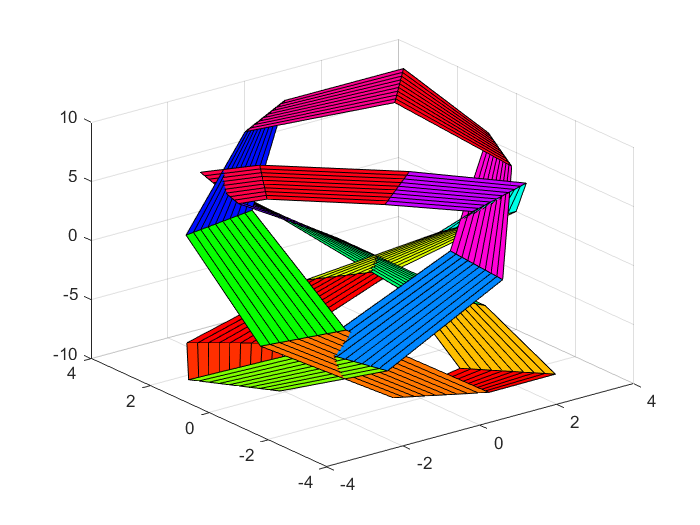

[ui,vi] = meshgrid(0:0.01:2*pi,-1:0.01:1);

xx = interp2(u,v,x,ui,vi,'spline');
yy = interp2(u,v,y,ui,vi,'spline');
zz = interp2(u,v,z,ui,vi,'spline');
surfl(xx,yy,zz,'light'), colormap hsv, shading interp

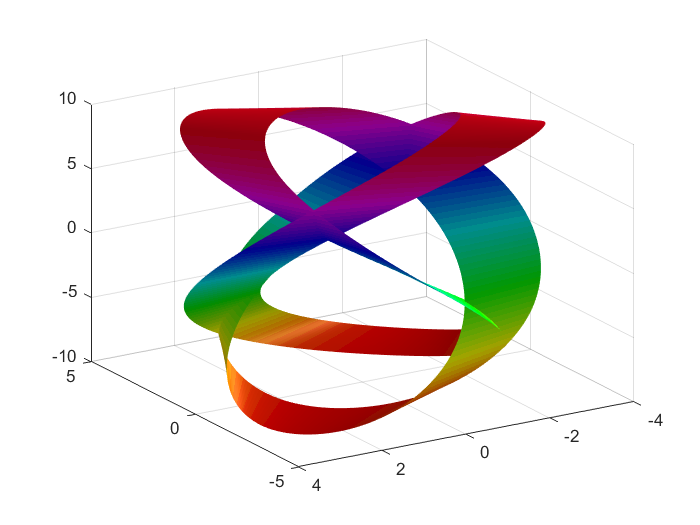

view([238.2 25.7])

Dall'esempio si evince chiaramente come per effetto dell'interpolazione dei punti mediante la `spline`, una superficie spigolosa e irregolare, abbia acquistato regolarita e come come la superficie stessa sia diventata più `"liscia"` .

# Smoothing di dati

In questa serie di esempi si vuole analazziare il set di funzioni `Matlab` che permettono di effettuare lo smoothing di dati, ovvero di applicare dei filtri il cui scopo è evidenziare i pattern significativi. Permettendo, ad esempio, di attenuare il rumore presente intrinsicamente nei dati misurati con strumenti non ideali oppure per ridurre il grado di incertezza su dati di tipo statistico.

## Temperature medie in Italia dal 1901 al 2012

In questo esempio si è utilizzato un dataset di temperature messo a disposizione da [wordbank.org ](http://www.worldbank.org/)[2] che riguardano le temperature medie annuali misurate in italia dal 1901 fino al 2012.

Come prima cosa scarichiamo il dataset utilizzando le C`limate Data API [1] `messe a disposizione da [wordbank.org](https://www.worldbank.org) [2], poi separiamo i dati in anni e temperature e calcoliamo la temperatura media nel periodo.

url = 'http://climatedataapi.worldbank.org/climateweb/rest/v1/country/cru/tas/year/ita';
options = weboptions('Timeout',Inf);  
data = webread(url,options);

% Carico i dati nelle variabili e calvolo la media
rawData = table2array(struct2table(data));
year = rawData(:,1);
temperature = rawData(:,2);

meanTemp = mean(temperature)

meanTemp = 12.4158

Si è poi calcolato il valor medio di temperatura nel periodo e si è utilizzata l'interpolazione lineare a tratti per generare il seguente grafico.

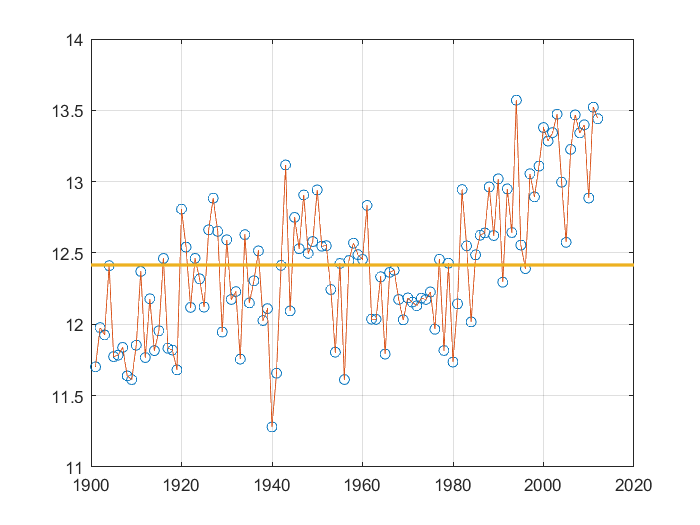

t = 1901:0.1:2012;

% interpolazione lineare a tratti
z = interp1(year,temperature,t);
p = plot(year,temperature,'o',t,z,[1900 2020],[meanTemp,meanTemp]); grid
p(3).LineWidth = 2;

maxEx =max(abs( meanTemp - temperature))

maxEx = 1.1553

Inoltre possiamo anche osservare, che nel periodo preso in esame, abbiamo un escursione massima di 1.15° .

Applicando le tecniche di smoothing è possibile osservare ulteriori informazioni che in una prima analisi potrebbere sfuggire. Infatti interpolando utilizzando la spline otteniamo una curva con un comportamento più regolare assumendo comunque che i valori siano ancora affetti da un errore di misurazione e uno di tipo statistico di cui non abbiamo nessuna informazione. Interpalando utilizzando la retta dei minimi quadrati si può evidenziare come nel corso del secolo la temperatura sia mediamente aumentata per un'escursione termica complessiva di circa 1°. Inoltre si è proceduto anche all'interpolazione utilizzando il polinomio di secondo grado. Da tutte le curve presenti sul grafo sottostante notiamo l'aumento di temperatura che si è avuto dalla fine degli anni '70 ad oggi. Infatti della curva generata a partire dal polinomio di secondo grando e da quella generata con la spline, si evince come aumenta la pendanza negli ultimi decenni. Ciò ci fa capire come la temperatura sia in aumento negli ultimi decenni e che un analisi di questo tipo è utile anche ai fini di quantificare il problema del surriscaldamento globale.

coeff1 = polyfit(year,temperature,1);
coeff2 = polyfit(year(1:10:112),temperature(1:10:112),2);

**Nota :** il poliniomo di secondo grado, pur evidenziando un comportamento crescente, non può essere usato per alcuna analisi in quanto come negli esempi precedenti la presenza di molti punti lo rende mal condizionato.

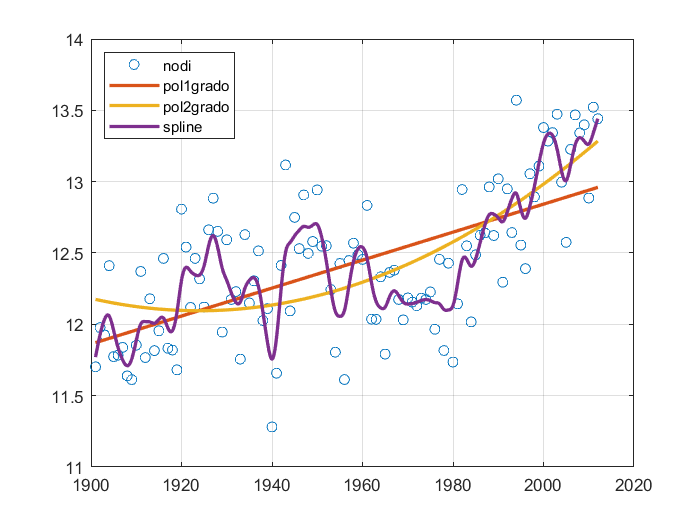

t = 1901:0.1:2012;

% costruisco i polinomi
f1 = polyval(coeff1,t);
f2 = polyval(coeff2,t);

pp = csaps(year,temperature,0.45);
ys1 = ppval(pp,t);
p = plot(year,temperature,'o',t,f1,t,f2,t,ys1); grid
legend('nodi','pol1grado','pol2grado','spline','Location','northwest')
p(4).LineWidth = 2; p(2).LineWidth = 2; p(3).LineWidth = 2;

## Andamento mensile delle azioni del gruppo FCA dal 2013 al 2019

Come ulteriore esempio per lo smoothing dei dati abbiamo preso l'andamento delle azioni del gruppo **FIAT, **poi diventato gruppo** FCA,** nel periodo che va da gennaio del 2013 a maggio del 2019, al fine di evidenziare come sono variati i valori delle azioni in riferimento ad alcuni eventi di interesse. Il dataset è stato preso da [yahoo finanza](https://finance.yahoo.com/quote/FCA.MI) [3] e punti del grafo indicano il prezzo medio per azione nel mese di riferimento. 

**Nota:** Prima di procedere con l'esempio pratico, si vuole sottolineare che i dati sono affetti da errore statistico, in quanto i valori presenti nel dataset sono ottenuti effettuando la media dei valori delle azioni che variano giorno per giorno.

Iniziamo col caricare il dataset e mostrare come si presentano i dati e evidenziamo alcune date d'interesse che dopo andremo ad analizzare.

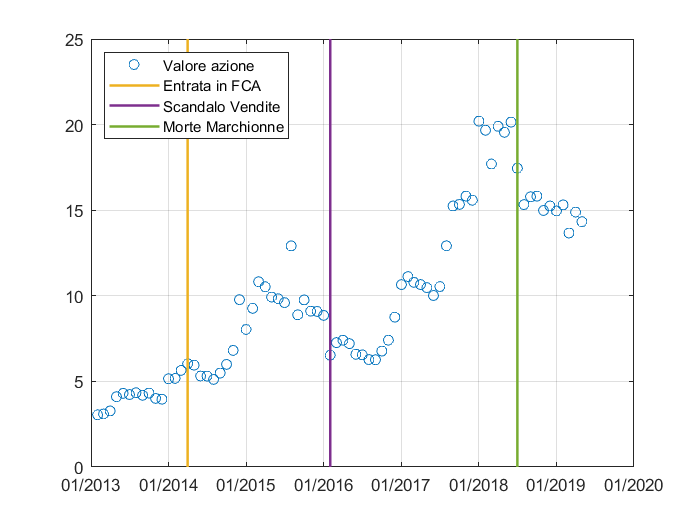

MM       = csvread('FCA.MI.csv',2,2);
azioni   = MM(:,1);
nMonth   = size(azioni,1);
t1       = datetime(2013,1,1);
t        = t1+calmonths(1:76);

% Interpolo i dati con la spline
figure(32)
p = plot(t,azioni,'o',[t(15),t(15)],[0,25],'y',[t(37),t(37)],[0,25],[t(66),t(66)],[0,25],'g'); grid
p(2).LineWidth=1.5;p(3).LineWidth=1.5;p(4).LineWidth=1.5;
set(p, {'color'}, {[0 0.4470 0.7410];[0.9290 0.6940 0.1250];[0.4940 0.1840 0.5560];[0.4660 0.6740 0.1880]});
legend('Valore azione','Entrata in FCA','Scandalo Vendite','Morte Marchionne','Location','northwest')
datetick('x','mm/yyyy')

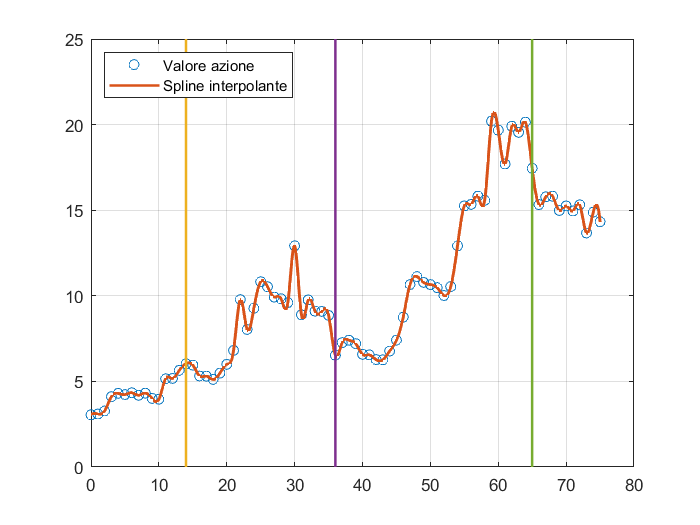

Months  = 0:nMonth-1;
pp      = spline(Months,azioni);
tSpline = 0:0.1:nMonth-1;
ySpline = ppval(pp,tSpline);

p = plot(Months,azioni,'o',tSpline,ySpline,[14,14],[0,25],[36,36],[0,25],[65,65],[0,25]); grid
p(2).LineWidth=1.5;p(3).LineWidth=1.5;p(4).LineWidth=1.5;p(5).LineWidth=1.5;
legend('Valore azione','Spline interpolante','Location','northwest')

Se presentassimo questo primo grafico a dei futuri azionisti che magari hanno scarsa conoscenza di economia e di statistica, sicuramente non sarebbero motivati ad investire nell'azienda, in quanto potrebbero chiaramente osservare che il valore delle azioni è abbastanza instabile, in alcuni mesi la singola azione ha perso anche il `30%` del suo valore e in altri ha guadagnato anche il `50%` del proprio valore.

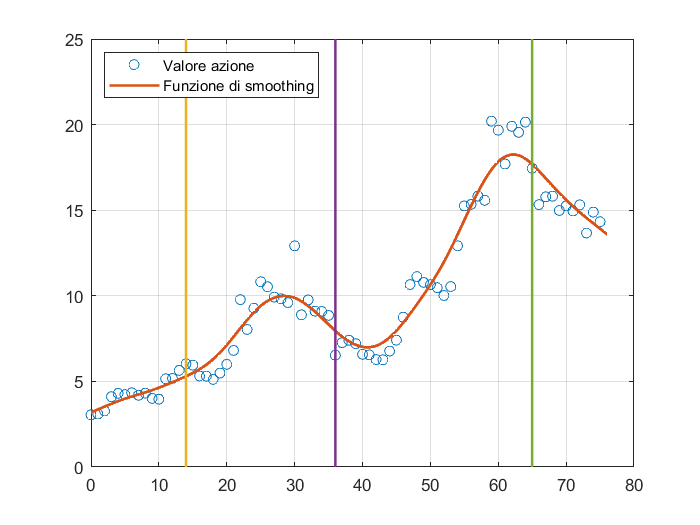

% Per effettuare il plot sullo stesso grafico c'è bisogno che sull'asse
% delle x ci siano variabili di uno stesso tipo

% costruisco la funzione di smoothing e calcolo i punti
tSpline = 0:0.1:nMonth;
pp = csaps(Months,azioni,0.01);
ys1 = ppval(pp,tSpline);

p = plot(Months,azioni,'o',tSpline,ys1,[14,14],[0,25],[36,36],[0,25],[65,65],[0,25]); grid
p(2).LineWidth=1.5;p(3).LineWidth=1.5;p(4).LineWidth=1.5;p(5).LineWidth=1.5;
legend('Valore azione','Funzione di smoothing','Location','northwest')

Nel caso presentassimo questa curva un azionist sarebbe molto più motivato ad investire nell'azienda. Inoltre possiamo anche sottolinerare che dall'aprile del 2014, mese in cui il gruppo **FIAT** entra a far parte del gruppo **FCA, **c'è stata una crescita quasi costante che ha portato ad aumentare il valore delle azioni. Un ulteriore evento di interesse si è presentato agli inizi del 2016, quando uno scandalo ha colpito **FCA **negli USA [4], ma dopo essersi ripresa la sua crescita è continuata, fino alla morte dell'amministratore delefato, Sergio Merchionne. Quest'ultimo è stata una figura molto importante per il rinnovamento che ha intessato prima il gruppo **FIAT** e poi il gruppo **FCA**, infatti dopo la sua morte le azioni sono crollate, ma come è già successo in passato il gruppo si riprenderà sicuramente.

## Interpolazione per migliorare le immagini 

Utilizzando le funzioni di interpolazione offerte dal Matlab si può migliorare anche la qualità delle immagini, infatti non bisogna dimenticare che le immagini sono delle matrici di punti che hanno delle informazioni relative ai colori del punto.

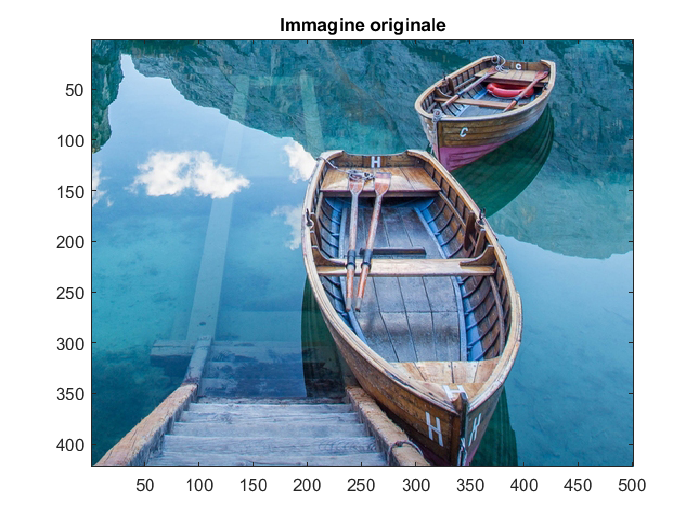

Image = imread('foto.jpg');
resizedImage = imresize(Image, 0.45);

[r,c,v] = size(resizedImage);
x = 1:c; y = 1:r;

splineImage = zeros(5*r,5*c,v,'uint8');
linearImage = zeros(5*r,5*c,v,'uint8');

% Scelgo una grana più fine per i punti della nuova immagine
newX = linspace(1,c,5*c)';
newY = linspace(1,r,5*r);

for i=1:3
    splineImage(:,:,i)=uint8(interp2(x,y,double(resizedImage(:,:,i)),newX,newY,'spline'));
    linearImage(:,:,i)=uint8(interp2(x,y,double(resizedImage(:,:,i)),newX,newY,'linear'));
end
image(Image),title('Immagine originale')

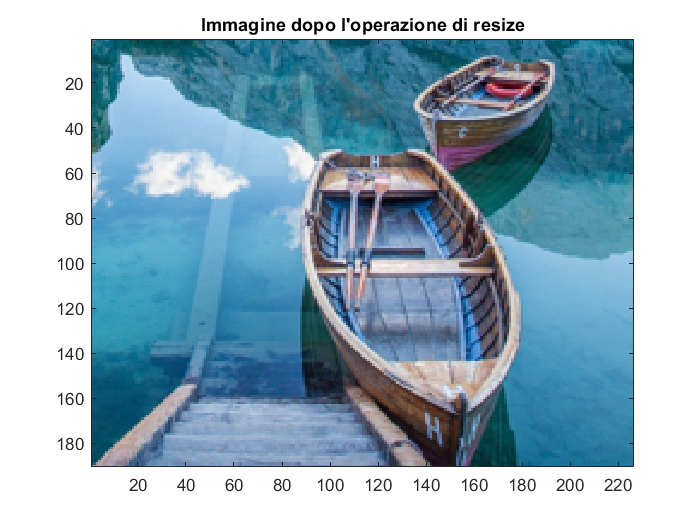

image(resizedImage),title('Immagine dopo l''operazione di resize')

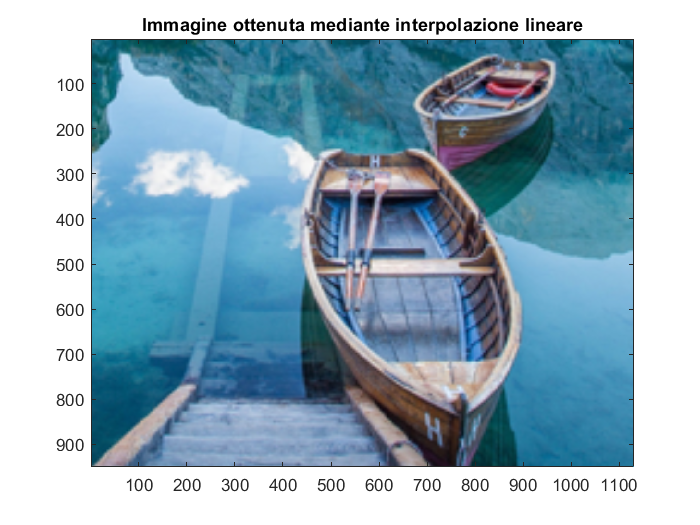

image(linearImage),title('Immagine ottenuta mediante interpolazione lineare')

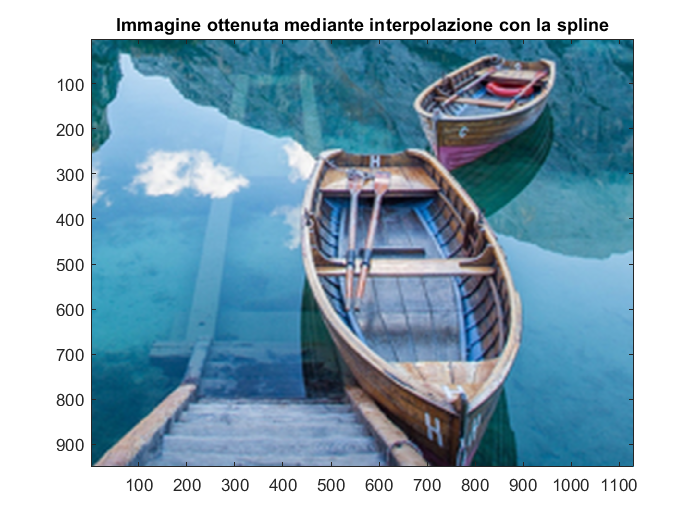

image(splineImage),title('Immagine ottenuta mediante interpolazione con la spline')

Per osservare il miglioramento ottenuto duranto tale processo di iterpazione, prendiamo come riferimento la lettera "c" presente sulla barca in secondo e vediamo come essa si presenta nel caso dell'immagine dopo il resize, dopo l'interpolazione lineare e dopo l'interpolazione con la spline.

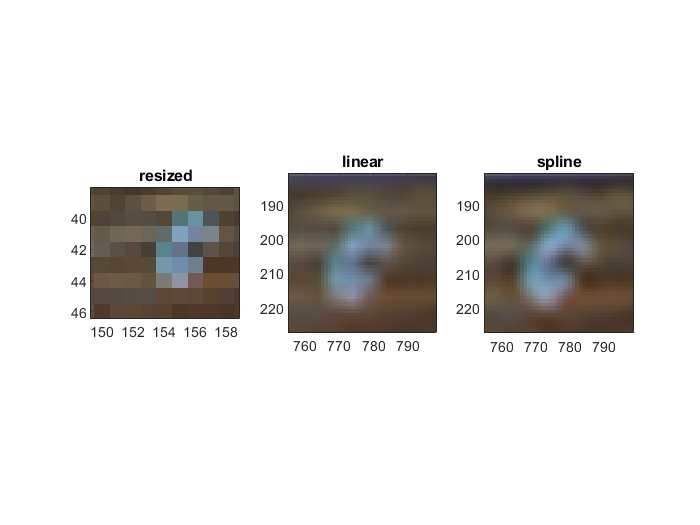

subplot(1,3,1), subimage(resizedImage),title('resized')
subplot(1,3,2), subimage(linearImage),title('linear')
subplot(1,3,3),subimage(splineImage),title('spline')

subplot(1,3,1)
xlim([149.29 158.87])
ylim([38.01 46.45])
subplot(1,3,2)
xlim([754.9 798.6])
ylim([180.7 227.3])
subplot(1,3,3)
xlim([754.9 798.6])
ylim([180.7 227.3])

Si noti come l'area selezionata, che a sinistra rappresenta qualcosa di incomprensibile, migliori con l'interpolazione e con qualla che utilizza la `spline` si riesce a capire che quella che sembra una macchina bianca sulla seconda barca nell'immagine dopo il resize è in realtà la lettera `'C'.`

## **Riferimenti**

[1] Climate data API : [https://datahelpdesk.worldbank.org/knowledgebase/articles/902061-climate-data-api](https://datahelpdesk.worldbank.org/knowledgebase/articles/902061-climate-data-api)

[2] Wordbank.org : [http://www.worldbank.org/](http://www.worldbank.org/)

[3] Yahoo Finanza,azioni FCA : [https://finance.yahoo.com/quote/FCA.MI](https://finance.yahoo.com/quote/FCA.MI)

[4] Scandalo vendite false negli USA, articolo del sole 24 ore : [Articolo](https://www.ilsole24ore.com/art/finanza-e-mercati/2016-01-14/fca-crolla-piazza-affari-automotive-news-vendite-truccate-usa-112128.shtml?uuid=ACx5pt9B)

## Autore

Gabriele Previtera